依赖[统一实验分析作图v17.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

DataSet=TransferLearning.FullCalcium;
Calcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'光声迁移'),UniExp.Flags.log2FdF0,1:24,UniExp.Flags.Median));

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1])

Colors =     1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000    0.0000


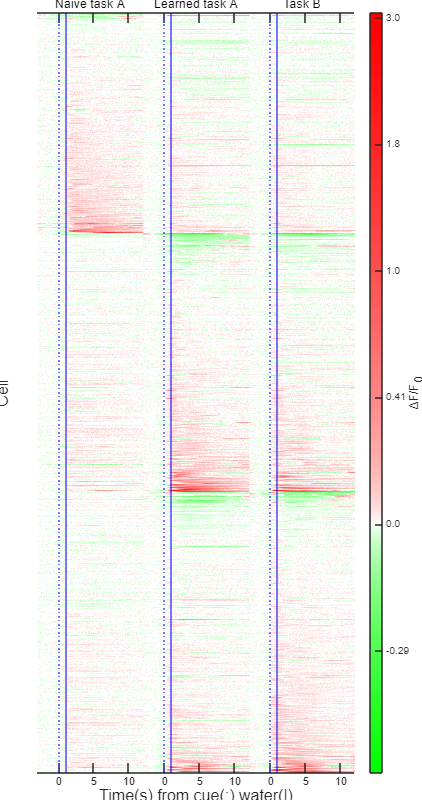

TransferLearning.AucGroupSortedHeatmap(Calcium.NTATS{:,:,["Naive_task_A","Learned_task_A","Task_B"]},["Naive task A","Learned task A","Task B"],Colors([3,1,2],:),true);
MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('Fig1G.svg'),'-dsvg');